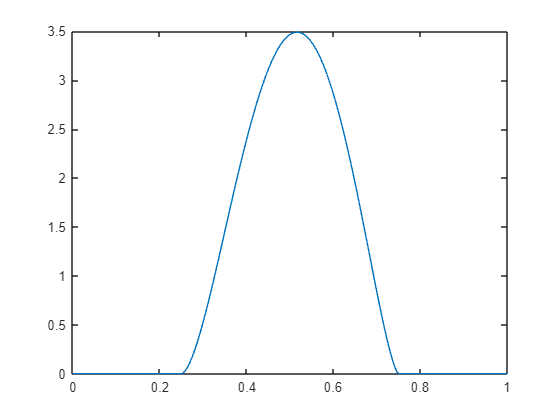

mu = .51;
sigma = .1;

density = @(p) (p >= 1/4 & p <= 3/4).*power(4*p-1,(4*mu-1)*(4*mu-1)*(3-4*mu)/32/sigma/sigma-2*mu-1/2)...
                                     .*power(3-4*p,(4*mu-1)*(3-4*mu)*(3-4*mu)/32/sigma/sigma+2*mu-5/2)...
                      /beta((4*mu-1)*(4*mu-1)*(3-4*mu)/32/sigma/sigma-2*mu+1/2,(4*mu-1)*(3-4*mu)*(3-4*mu)/32/sigma/sigma+2*mu-3/2)...
                      /power(2,(4*mu-1)*(3-4*mu)/16/sigma/sigma-4);

x_mesh = 0:.001:1;
density_values = density(0:.001:1);

plot(x_mesh,density_values)
hold on


area = integral(density,0,1)

area = 1.0000


% Mean
mean = integral(@(p) modified_beta(p,mu,sigma).*p,0,1)

mean = 0.5100


% Standard Deviation
stdev = sqrt(integral(@(p) modified_beta(p,mu,sigma).*power(p-mean,2),0,1))

stdev = 0.1000

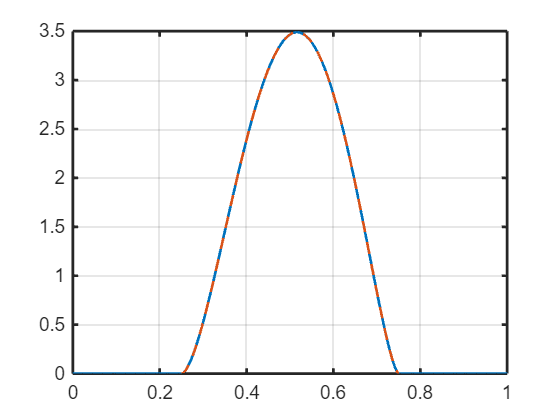

% A "Real" Beta Distribution

a = (4*mu-1)*(4*mu-1)*(3-4*mu)/32/sigma/sigma-2*mu+1/2;
b = (4*mu-1)*(3-4*mu)*(3-4*mu)/32/sigma/sigma+2*mu-3/2;

x_mesh_transformed = (x_mesh+1/2)/2;
beta_values = 2*betapdf(x_mesh,a,b);
plot(x_mesh_transformed,beta_values,'LineStyle','--')
sexy_plot

% CDF and Inverse CDF

density_cdf = @(p) betacdf(2*p-1/2,(4*mu-1)*(4*mu-1)*(3-4*mu)/32/sigma/sigma-2*mu+1/2,(4*mu-1)*(3-4*mu)*(3-4*mu)/32/sigma/sigma+2*mu-3/2);

for x = [.37 .43 .52 .61 .63 .73]
    fprintf('%d vs %d\n',integral(@(p) modified_beta(p,mu,sigma),0,x),modified_beta_cdf(x,mu,sigma))
end

9.194916e-02 vs 9.194915e-02
2.346089e-01 vs 2.346090e-01
5.301365e-01 vs 5.301365e-01
8.192544e-01 vs 8.192544e-01
8.698169e-01 vs 8.698164e-01
9.981133e-01 vs 9.981132e-01



cdf_inverse = @(d) 1/4+1/2*betainv(d,(4*mu-1)*(4*mu-1)*(3-4*mu)/32/sigma/sigma-2*mu+1/2,(4*mu-1)*(3-4*mu)*(3-4*mu)/32/sigma/sigma+2*mu-3/2);

for x = [.37 .43 .52 .61 .63 .73]
    fprintf('%d vs %d\n',x,modified_beta_cdf(modified_beta_inverse_cdf(x,mu,sigma),mu,sigma))
end

3.700000e-01 vs 3.700000e-01
4.300000e-01 vs 4.300000e-01
5.200000e-01 vs 5.200000e-01
6.100000e-01 vs 6.100000e-01
6.300000e-01 vs 6.300000e-01
7.300000e-01 vs 7.300000e-01
